# Data Fitting In MATLAB

Kurt Wick (wick@umn.edu) 8/7/2018

Based on: FittingWriteup2018V4h.mlx

## Introduction / Purpose

This report outlines data fitting in the physical sciences using MATLAB’s versatile and powerful ‘fit’ function, which utilizes a least-squares algorithm. The emphasis is on how to use the fit function and interpreting the fit results; explanations on the theory of statistics are kept to a minimum. (Sources on MATLAB and Statistics are listed at the end.) The entire fitting procedure is presented as a MATLAB Live Script which can be modified to be used for any data as long the input is in the form of column vectors x, y, sig_y.

For the exercises and discussion, we will fit the data to a simple 2nd order polynomial, i.e., a straight line.  However, it would have been simple to fit it to other, non-linear curve models which are provided in the MATLAB library. Also, the discussion is kept general and applies also to non-linear fitting.

This Live Script is broken into three distinct sections which can be run individually.   (In MATLAB, open the *LIVE EDITOR* tab, click on the section you want to execute and select “*Run Section*.”)  Section 1 generates a linear data set that is then being stored in your current folder; section 2 reads the data back into MATLAB and section 3 fits and analyzes the data.  This approach allows the user to experiment with identical and different data sets, depending on the sections executed, and to observe the corresponding effect on the fits.  This Live Script also provides the user with a ready to use template to fit their own data by modifying section 2 and reading in their data.

The appendices contain detailed information on the fit function and the information it returns.  Links to the corresponding documentation within MATLAB or Mathwork’s website are also provided in individual sections.  (Clicking and running a specific section will bring up MATLAB’s help screen on that subject.)  Finally, since the actual fitting procedure in section 3 is accompanied by detailed commentaries, a lean version of it, without the commentaries, has been provided in the last section.  You may use it and integrate it into your own script.

## Introduction to Data Fitting 

Assume that we have acquired *n* measurements of, $x_i$ and ${\mathrm{ym}}_i$ (where *x* is the independent and *ym* the dependent variable) and that we "know" the uncertainty or error associated with each measurement, i.e., $\sigma_{{\mathrm{ym}}_i }$.  Typically we want to fit this data set to some model: ${\mathrm{yf}}_i =\mathrm{yf}\left(x_i \right)$.

Generally we strive to select a fit model with the fewest parameters.  Applying the principle of Occam's razor we try to avoid (whenever possible) models with large numbers of fit parameters because they complicate the analysis and interpretation.  In this particular example, we select a straight line fit with two (adjustable) parameters *p1* and *p2* such that: ${\text{yf}}_i =\text{ }\text{p1}\text{ }x_i \text{ }+\text{ }\text{p2}$.

To determine the “best” fit parameters of our data for the selected fit model, we will apply a common algorithm called least squares minimization.  Its basic idea is simple and relies on the following steps:

1. Begin with some educated guesses for the fit parameters and apply these to the selected fit model to calculate the corresponding fit values, ${\mathrm{yf}}_i =\mathrm{yf}\left(x_i \right)$ for each $x_i$.

2. For every data point, calculate how far our model ${\text{yf}}_i$ deviates from the measured value ${\text{ym}}_i$  by determining its $\chi_i \text{ }$ (pronounced "chi of i"):

            $\chi_i =\frac{{\mathrm{yf}}_i -{\mathrm{ym}}_i }{\sigma_{{\mathrm{ym}}_i } }$                                   (Equation 1.)

This value is also sometimes called the weighted residual and it describes how many standard deviations a data point is "off" from our model. 

3. Next we square and then sum all the $\chi_i \text{ }$values as shown below:

        $\text{SSE}=\chi^2 =\text{ }\sum_i \chi_i^2 =\sum_i {\left(\frac{{\text{yf}}_i -{\text{ym}}_i }{\sigma_{{\text{ym}}_i } }\right)}^2 \text{ }$  (Equation 2.)

and obtain the $\chi^2$ or the sum of squares due to error, or SSE for short, for our particular choice of fitting parameters.

4. We then adjust our fit parameters and repeat the first 3 steps of this algorithm until we are reasonably certain that we have found the minimum $\chi^2$ (or SSE) value. Once we have reached this point we have found the best values for the fit parameters.  We are certain that these are the “best” fit parameters because these particular values will result in the smallest achievable error (squared) sum (SSE) of our data points to the selected model..

5. We have now completed our actual fitting process.  However, since it is possible to fit anything to any model, no matter how bad the fit - a process repeated all too often in real life - the challenge (or rather art) in fitting is interpreting the fit results and measuring the goodness of the fit (GOF.)  In short, does the data really fit the model? This question can be answered by looking at the myriad of data that the fit generates, specifically by examining the SSE vs. DFE (Degrees of Freedom) and by calculating the corresponding probability to exceed (PTE.)

6. Only, when we are satisfied with the results in step 5 does it make sense to look at the calculated fit parameters and their uncertainties and the correlation matrix.

Today’s computers and software are perfectly able to handle steps 1 through 4. In fact a simple, one-line MATLAB command, *fit*, will do most of the work.  All you have to do is to provide the data in the form of column vectors for *x*, *ym* and $\sigma_{\mathrm{ym}}$, select a fit model and out comes the result. However, where today’s computer (still) lack is step 5, examining the goodness of the fit and deciding if the selected model was optimal and if the data and the errors are acceptable. This will be your job!

# **Section 1:  Generating the Sample Data**

In the section below, a linear sample data set with Gaussian random noise is generated and plotted and then written to a file named 'LSQFitLinData_01.mat'.

clear all;
disp('*** Generate and Save a Linear Data Set: y = ax + b + noise ***')

*** Generate and Save a Linear Data Set: y = ax + b + noise ***


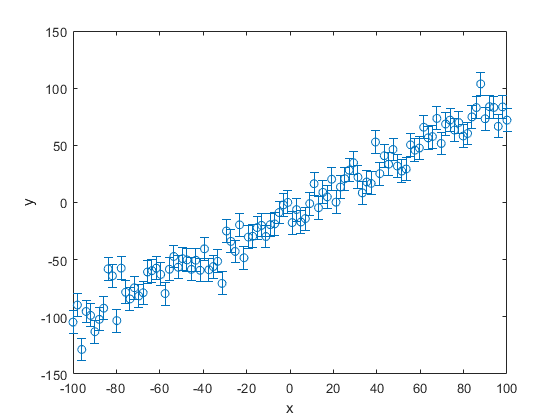

n = 100;    % number of data points to generate
x0  = -100; % x-value range (start)
x1  = 100;   % x-value range (end)
slope = 1;    % slope for the linear data set
offset = -10;    % offset for the linear data set
noiseamp = 10;    %Gaussian noise amplitude (standard deviation of generated noise)

% Now generate the data set
x_data = linspace( x0, x1, n)'; % generate the independent value (x) column vector with n elements of evenly spaced 
                               % data points between x0 and x1 
y_error = noiseamp.*ones( n, 1);% generate the sigma_y column (error in y) column vector 
y_noise  = y_error.*randn(n, 1); % generate Gaussian random noise
y_data = offset + slope.*x_data + y_noise; %calculate the dependent (y) values and add the noise
errorbar (x_data,y_data, y_error, 'o' ) %plot and label the data
xlabel('x')
ylabel('y')


% finally save the data to the file below and clear all variables.
save('LSQFitLinData_01.mat', 'x_data', 'y_data', 'y_error');
clear all;

# Section 2:  Reading the Data File

The previously created data file is read and plotted. The column vectors are assigned to the appropriately named variables so that they can be fitted in the next section.

If you have your own data, possibly in the form of an Excel spreadsheet, you may consider modifying the script below so that your data is read instead.  To import the Excel data, from MATLAB’s HOME tab, select “Import Data.”  Next, comment the line of script starting with “load” out by preceding it with a percentage sign. Finally, assign the names of your Excel column variable names to the corresponding column vectors x, y and sig_y.

disp('**** Load the Data Set and Plot It ****')

**** Load the Data Set and Plot It ****


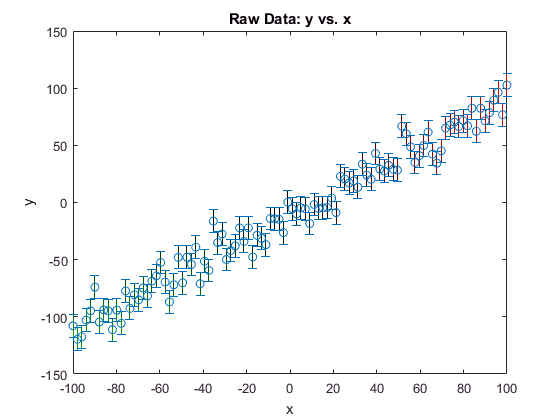

load('LSQFitLinData_01.mat')    %comment out if you are providing your own data

x = x_data; 	%assign data read-in to these variables so it can be fitted in the next section
y = y_data;
sig_y = y_error;

errorbar (x,y, sig_y, 'o' ) %plot the data with error bars
title('Raw Data: y vs. x')
xlabel('x')
ylabel('y')
hold off

# Section 3:  Fitting the Data Using a Least Squares Algorithm and MATLAB’s ‘fit’ Function

In this section the actual fitting is carried out. The fit parameters and their uncertainties are calculated together with indicators specifying how well the data fit the selected model.

## 3.1. Fit function

MATLAB’s *fit* function requires the following data input: the independent variable *x*, the dependent variable *y* and, for a weighted fit, a weighting factor *w* which is related to the uncertainty in y, $\sigma_y$, by:

        $w=\frac{1}{\sigma_y^2 }$                                             (Equation 4.) 

%use a least squares algorithm to fit the weighted data to a model
[fitobj, gof, outp] = fit(x, y,'poly1', 'Weights',(1./sig_y).^2)

fitobj =      Linear model Poly1:
     fitobj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9986  (0.9622, 1.035)
       p2 =      -11.39  (-13.51, -9.266)

gof = struct with fields:
           sse: 111.8908
       rsquare: 0.9681
           dfe: 98
    adjrsquare: 0.9677
          rmse: 1.0685


outp = struct with fields:
        numobs: 100
      numparam: 2
     residuals: [100×1 double]
      Jacobian: [100×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


In the line of code shown above, the data is fit to a first order polynomial, i.e., a straight line, by specifying ‘poly1’ as our fit model.  (A detailed description of other MATLAB fit models and their equations can be found in the Appendix.) 

The 'fit' function returns three objects. In the example shown they have been labeled: 'fitobj', 'gof' and 'outp.' These objects contain values for the fit parameters and their uncertainty as well as the goodness of the fit. Before examining them further, let's first visually inspect the actual fit by plotting the data and the best fit to the model.  

## **3.2. Plotting the Fit Data and Results**

Our eyes and brain constitute an amazingly sophisticated pattern recognition engine.  Often, a glance at the raw data and the fit results reveals a pretty good estimation of the quality of the fit.

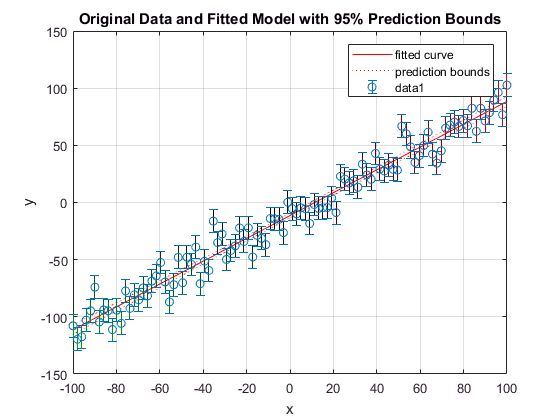

%plot the original data vs. the selected model
plot(fitobj, 'predfunc') % add another argument to change the default .95 conf. level
title('Original Data and Fitted Model with 95% Prediction Bounds');
xlabel('x')
ylabel('y')
grid on;
hold on
errorbar (x,y, sig_y, 'o' )
hold off

This plot also displays the (default) 95% prediction bounds or confidence interval.  This is the region we expect subsequent plot results to fall (with data collected under the similar circumstances) 95% of the time. (Note: though the 95% confidence interval is used extensively in engineering, physicists express the accuracy usually in a different way as we will see shortly.) 

If the fitted curve does not lie within the cluster of your input data then check for bad data points, i.e., outliers, which may distort the fit results.  If removing the outliers doesn't work, you may need to select a different fit model. 

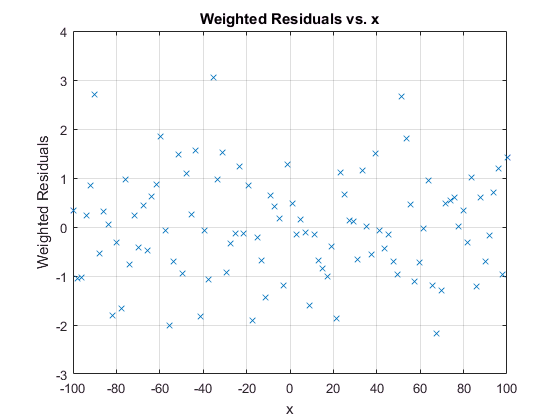

% Plot the weighted residuals (residuals divided by their standard deviation)
plot(x(1:length(outp.residuals),:), outp.residuals, 'x')
title('Weighted Residuals vs. x')
xlabel('x')
ylabel('Weighted Residuals')
grid on

The second plot displays the weighted residuals for each data point. (See equation 1 for its definition.)  It expresses (in units of standard deviations) how far removed each data point is from the best fit. 

A glance at the weighted residuals plot may reveal trends in your data. If that’s the case, then maybe you should try a different model.

For data with Gaussian noise, we expect about 2/3 of our data points to fall within $\pm \text{ }1$ standard deviations. This means that about 2/3 of the data points should have weighted residual values between -1 and +1. By similar reasoning, 95% of all our data points should lay in the weighted residual region from -2 to +2.

Important: from the criterion listed in the preceding paragraph, the weighted residual plot should confirm that your data’s uncertainties, $\sigma_y$, are reasonable. Since it is notoriously difficult making proper assumptions about $\sigma_y$, this initial confirmation is crucial and indicates that the remaining fit results are meaningful. However, if your plot results do not satisfy the above listed criterion, then you should go back and examine your $\sigma_y$ values because most of the fit results will be meaningless. (If most of the residuals exceed the -1 to +1 region, then you have underestimated your $\sigma_y$; conversely, if the vast majority of your residuals fall into a region far smaller than -1 to +1 than you have greatly overstated your $\sigma_y$ and you should find out why you need to reduce it.)

At this point you may also check for outliers.  These are individual data points with the absolute value of the weighted residuals exceeding 4 sigmas.  Decide how to deal with them; if you choose to exclude these from your analysis, be sure to document that fact in your analysis discussion!

Of course, we don’t expect you to count each data point and see if meets the criterion laid out above for the weighted residual plots. MATLAB compiles these metrics and in the next section you will see how to use them. However, since there are often multiple causes for a bad fit, it is important to first examine the results through a graphical representation like the plots shown above.

## **3.3. Goodness of Fit, (GOF): Degrees of Freedom, (DFE), the Sum of the Squares due to Error, (SSE) or **$\chi^2$** and the Probability to Exceed, (PTE)**

The two most important quantities describing the quality or “goodness” of a fit are the “sum of the squares due to error,” (SSE), also known as the chi squared, $\chi^2$**,** and the degree of freedom, DFE.  Both of these values are returned by ‘gof’ structure of the fit function.

As shown in equation 2, the SSE (or $\chi^2$) represents the sum of all weighted residuals squared and it is this value that the fitting algorithm attempts to reduce to its minimum value to determine the best fit to our selected model.  As indicated in the previous section, for data with Gaussian noise we expect about 2/3 of the data points to have an absolute value of the weighted residual of 1 or less. Without further proof, this then leads us to conclude that for *n* data points, the sum all weighted residuals squared, i.e., the SSE or $\chi^2$ should be “roughly” equal to *n*.  In other words: SSE ≈ *n*.

However, a more accurate prediction takes into account the “degrees of freedom” or DFE of the fit.  The DFE expresses how much freedom the algorithm has to “tweak” the SSE to obtain its minimum value.  This depends on two factors, namely the number of data points, *n*, (or simultaneous equations it tries to minimize) and the number of fit parameters, *m*, it has to satisfy.  It is defined by:

        $\mathrm{DFE}=n-m$                             (Equation 5.) 

For example, if we have only 2 data points for a fit to a straight line (which has 2 parameters, the slope and the offset) then we don’t have any “wiggle” room and line is completely defined and will pass through both points resulting in an SSE = 0.  However, if we have one extra data point, then we have one degree of freedom and our fitting algorithm will determine the slope and offset for a straight line that is closest to all three of them.  Since any 2 of the 3 points will fall directly on the straight line, by Gaussian statistics we expect the third point to be about 1 standard deviation away, i.e., we expect an SSE of 1.

From this it follows then that for Gaussian noise, ideally:

        $\mathrm{SSE}=\mathrm{DFE}$                                (Equation 6.)

Since this relationship is an important measurement of the goodness of a fit, it has been given its own name, the “reduced chi square,” written as $\chi_{\nu }^2$ and it is defined as:

        $\chi_{\nu }^2 =\frac{\mathrm{SSE}}{\mathrm{DFE}}$                                    (Equation 7.)

In the “ideal” case, $\chi_{\nu }^2$ = 1 and you may think of $\chi_{\nu }^2$ representing the “average” weighted residual squared.  It is being calculated below:

fprintf('Reduced Chi Squared: %E\n', gof.sse/gof.dfe );

Reduced Chi Squared: 1.141743E+00


Based on the explanation for the range of weighted residuals, it follows than that $\chi_{\nu }^2$ values different from 1 indicate a problem with our fit.  ($\chi_{\nu }^2$ exceeding 1 is caused by $\sigma_y$ values being too small, by outliers (check the weighted residual plot) or by selecting a “bad” model.  However, $\chi_{\nu }^2$ values for smaller than 1 indicate an overly generous estimate of $\sigma_y$.)

Using $\chi_{\nu }^2$  as a measure for the goodness of the fit leads to the question, what the acceptable range for $\chi_{\nu }^2$ is.  (For example, if you decide to run this entire simulation multiple times you will encounter significant fluctuations in $\chi_{\nu }^2$, especially as you decrease the number of data points generated.)  The answer to this question can be expressed with yet another statistical metric, namely the "probability to exceed" value, PTE.  It is based on the idea that the SSE or  $\chi^2$ for a particular data set can be represented by a probability distribution function, which in this case, not surprisingly, is called the "chi squared probability distribution" function.  It defines the chance of exceeding a particular SSE for a given DFE and it is calculated below:

% probability to exceed
pte = 1-chi2cdf(gof.sse,gof.dfe);
fprintf('PTE for SSE: %E and DFE: %E is: %E\n', gof.sse, gof.dfe, pte)

PTE for SSE: 1.118908E+02 and DFE: 9.800000E+01 is: 1.596354E-01


Ideally, you strive for a PTE of 0.5, indicating that 50% of the time your SSE would be larger (or smaller) than the value you obtained.  In many branches of science PTE values from 0.05 to 0.95 are considered acceptable; values outside of this range indicate a problem.

(Additional Information Regarding the PTE: when you run this demonstration multiple times, you will find that it is quite easy to get PTEs that are not acceptable, i.e., values that are outside the 5% to 95% range. This might be surprising given how “ideal” our (artificial) data set is since we do not have to worry about external noise and outliers. The reason for exceeding the acceptable PTE range is that when the data set is generated, we specify the generated noise level but we do not verify it by calculating its actual standard deviation.  Instead, we proceed with the analysis under the assumption that the generated noise has the specified standard deviation which we then use for our $\sigma_y$.  However, there is noise in the noise, and the standard deviation of the noise fluctuates (slightly) between runs.  With the values of  $\sigma_y$ being so crucial to the entire analysis, small discrepancies can seriously affect the PTE calculations.

You could easily fix it: it would involve measuring the actual standard deviation of the noise generated.  This can be achieved by adding the statement shown below:

`Y_error = std(y_noise)*ones( n, 1);`

Insert it towards the end of section 1 where the data set is generated.  This modification to our code will consistently yield good PTE values.  However, adding this measurement is unrealistic; it relies on separating the noiseless data from the noisy dataset to measure its standard deviation, a luxury one unfortunately rarely gets in real life since the acquired data is already contaminated by the noise.)

## **3.4. The Fit Parameters and their Uncertainties**

The final step in the fit procedure is determining the actual fit parameters and their uncertainties and correlations between them.

The MATLAB fit function displays the fit parameters and (by default) lists their uncertainties within the 95% confidence interval.  Since this interval corresponds roughly to two standard deviations, it is similar to expressing the uncertainty in a variable named ‘*q’* as: $q\text{ }\left(-2\sigma_q ,+2\sigma_q \right)$.

However, in science, uncertainties are typically expressed in terms of one standard deviation, as in: $q\pm \sigma_q$.  To determine this one sigma uncertainty, we have two methods.  A quick (and not necessarily reliable) way is to calculate one sigma from MATLAB’s default 95% confidence interval, noting that one sigma corresponds to ¼ of the interval.  A more robust and prefered technique, also shown below, obtains the uncertainties using the Jacobian matrix, as explained in Hughes, section 7.2., page 92.

So far, we have assumed that the fit parameters are independent of each other.  In other words, they are not correlated at all with each other.  To test the degree of correlation, we finally calculate and display the covariance or error matrix and the correlation matrix of the fit parameters.  The off-diagonal elements of these matrices indicate the degree to which the parameters are correlated, 0 indicating that there is no correlation.  For a more detailed discussion of its significance and how to apply it to the error propagation when the off-diagonal elements are non-zero, see this report's Appendix F, or: Hughes, section 7.4., page 95.

disp('Covariance or Error Matrix:')

Fit Parameters and Uncertainties (+/- One Standard Deviation)


p1: 9.985956E-01 +/- 1.714816E-02


p2: -1.138685E+01 +/- 1.000000E+00


error_matrix
disp('Correlation Matrix: ')

Covariance or Error Matrix:


corrm = error_matrix./sqrt(dcov*dcov')

error_matrix =     0.0003   -0.0000
   -0.0000    1.0000


## Curve Fitting App

MATLAB comes with a “Curve Fitting App” installed which can be located under the “APPS” tab.  It is the “app” version of the* fit *function and it uses the same input parameters as previously discussed namely, *x*, *y*, and, if desired, the weights, *w*, which are related to the uncertainty in *y*, $\sigma_y$, by Equation 4.  Since it is an app, it will not provide quite as much flexibility and information as the script above.  However, it certainly is a quick and easy way to get started on a fitting process.  **Warning:** the app can display the residue of the fitting function.  However, the diplayed residues in the fitting app are non-weighted and, therefore, completely independent of the weighting factor sig_y!

# Appendix A: References for Statistics and MATLAB

A concise treatment of statistics and error analysis can be found in the following book:  

- Hughes, Hase. *Measurement and their Uncertainties*, New York, NY: Oxford, 2010.

An excellent text book covering the mechanics of MATLAB such as vector and matrix manipulation, functions, programming and graphics is: 

- Attaway, Stormy. *Matlab, A Practical Introduction to Programming and Problem Solving 4th Edition*, Cambridge, MA: Elsevier, 2017.

We will be posting additional material on our MXP Google site at: 

[https://sites.google.com/a/umn.edu/mxp/home/matlab-notes](https://sites.google.com/a/umn.edu/mxp/home/matlab-notes)

# Appendix B:  Detailed Information and Resources Regarding MATLAB's *fit* Function

% [fitobj, gof, outp] = fit(x, y,'poly1', 'Weights',(1./sig_y).^2)

Correlation Matrix: 


## Built-In Fit Models

As shown in the code above, the data is fit to a straight line by specifying a first order polynomial, *‘poly1*’, as the fit model.  Shown below are the most common fitting models.  A more detailed description and additional MATLAB models can be found in the help section listed below.

**Model Name       Equation**

`poly1           Y = p1*x+p2`

`poly2           Y = p1*x^2+p2*x+p3`

`poly3           Y = p1*x^3+p2*x^2+...+p4`

...etc., up to:

`poly9           Y = p1*x^9+p2*x^8+...+p10`

`weibull         Y = a*b*x^(b-1)*exp(-a*x^b)`

`exp1            Y = a*exp(b*x)`

`exp2            Y = a*exp(b*x)+c*exp(d*x)`

`gauss1          Y = a1*exp(-((x-b1)/c1)^2)`

`gauss2          Y = a1*exp(-((x-b1)/c1)^2)+a2*... exp(-((x-b2)/c2)^2)`

`gauss3          Y = a1*exp(-((x-b1)/c1)^2)+... +a3*exp(-((x-b3)/c3)^2)`

...etc., up to:

`gauss8          Y = a1*exp(-((x-b1)/c1)^2) +... +a8*exp(-((x-b8)/c8)^2)`

`power1          Y = a*x^b`

`power2          Y = a*x^b+c`

For more information see:

[https://www.mathworks.com/help/releases/R2017b/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl](https://www.mathworks.com/help/releases/R2017b/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl)

## **Creating your Own Fit Model Function**

If there is no suitable fit model in the library, you can define your own fit function using 'fittype.'  You can then reference it from the standard fit function as shown in the example below.  (To execute, uncomment the last two lines by removing the leading '%'.)

% Create a new linear fit function named 'myf,' which is then called by the fit function:

corrm =     1.0000   -0.0000
   -0.0000    1.0000


%  myf=fittype('a+b*x')  % newly created function: y(x) = a + b*x
%  [fitobj, gof, outp] = fit(x, y,myf, 'Weights',(1./sig_y).^2)

(Of course, there is not much point in duplicating an already existing function like the one in the example shown above.)   

A second, more elaborate example, defining a logarithmic fit model, is shown below: (To execute, uncomment these two lines by removing the leading '%'.)

% myfittype = fittype('a + b*log(x)','dependent',{'y'},'independent',{'x'},'coefficients',{'a','b'})
% myfit = fit(x',y',myfittype)

For additional help on defining your own fit functions using ‘fittype,’ see: web(fullfile(docroot, 'curvefit/fittype.html')) or:

[https://www.mathworks.com/help/releases/R2017b/curvefit/fittype.html](https://www.mathworks.com/help/releases/R2017b/curvefit/fittype.html)

## Fit Objects

The *fit* function returns its results through three objects.  In the example shown above they have been labeled: *'fitobj'*, *'gof'* and *'outp.'* These objects provide the values for the fit parameters, their uncertainties, the goodness of the fit and information on the actual fit algorithm.  Below is a more detailed description of each of these objects or structures.

## *fitobj:* Fit Object

The fit object has the following methods associated with it:

- *coeffvalues*     - Get values of coefficients.

- *coeffnames*     - Coefficient names of cfit, sfit, or fittype object.

- *confint*             - Compute prediction intervals for coefficients.

- *differentiate*     - Compute values of derivatives.

- *feval*                - Evaluate at new observations.

- *integrate*          - Compute values of integral.

- *plot*                  - Plot a curve fit.  (Note: using *plot(fitobj)* behaves differently than the standard *plot* function; see the plot(fitobj) Appendix for a MATLAB help link)

- *predint*             - Compute prediction intervals for a curve fit or for new observations.

- *probvalues*      - Get values of problem parameters.

- *formula*            - Displays the fit model equation.

Shown below are some examples on how to use the *fitobj* methods.

For a quick display of the fit model and results, use:

fitobj % displays the fit object values

fitobj =      Linear model Poly1:
     fitobj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9649  (0.9258, 1.004)
       p2 =      -8.769  (-11.05, -6.487)

The individual fit parameter values can then be obtained from the *fitobj* either directly, by using their name, as shown in the linear fit object below:

myslope = fitobj.p1

myslope = 0.9649

myoffset = fitobj.p2

myoffset = -8.7691

Or, by using the *coeffvalues* method which will return a matrix of the fit parameters:

mycoeffs = coeffvalues( fitobj) %returns a matrix with fit parameters

mycoeffs =     0.9649   -8.7691


To calculate different prediction bounds, use the *confint* method. For example, to obtain the fit parameters values one sigma above and below, i.e., the 0.68 confidence interval, you would use:

confint( fitobj, 0.68)

ans =     0.9452   -9.9185
    0.9847   -7.6198


The fit object may also be called directly to calculate the fit model’s value, ${\mathrm{yf}}_i =\mathrm{yf}\left(x_i \right)$, for a specific $x_i$ as in:

xi = 0 %some x value

xi = 0

My_yfi = fitobj(xi)  %the corresponding fit model value aat xi

My_yfi = -8.7691

This method can be extended to an entire column vector, x, to calculate all the corresponding y values, as shown below:

Myfitted_values = fitobj(x)

Myfitted_values =  -105.2637
 -103.3143
 -101.3649
  -99.4156
  -97.4662
  -95.5168
  -93.5674
  -91.6180
  -89.6686
  -87.7193


It simplifies plotting the results of your fit as a function of x:

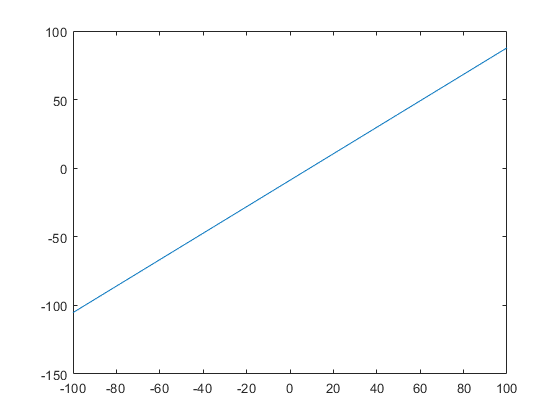

plot(x, fitobj(x)) % plot the fit model's values

The uncertainties in the fit model can be obtained by using the *predint *method. For example, calculating the +/- 1 sigma uncertainty, i.e., confidence level 0.68, in the fit model with xi = 0, can be obtained by:

predint( fitobj, 0, 0.68)  % calculate the fit models uncertainty

ans =   -10.3946   -7.1437


## 'gof' Goodness of Fit Object Structure

The `gof`** structure** includes the fields listed in the table below:

**Field                     Meaning**

`sse            `Sum of squares due to error  (Comment: this is identical to chi squared, $\chi^2$)

`rsquare        `R-squared (coefficient of determination)

`dfe            `Degrees of freedom in the error

`adjrsquare     `Degree-of-freedom adjusted coefficient of determination

`rmse           `Root mean squared error (standard error)

Comments: 

- 
$$\mathrm{sse}\equiv \chi^2$$


- The *rmse* is defined as$\mathrm{rmse}=\chi^2 /n$ where *n* represents the number of data points.  The reduced chi squared, $\chi_v^2$, has been defined as $\chi_v^2 =\chi^2 /DFE$.  However, for very large data sets, the number of data points, *n*, approaches DFE.  When this is the case, then $\chi_v^2$approaches *rmse*.  In other words, rmse may be used as rough iestimation of $\chi_v^2$.

These values can be accessed directly with the 'dot' notation, as in:

myrmse = gof.rmse

myrmse = 1.1499

## outp: 'output' Structure

The `output` structure includes the following fields:

**Field                    Value**

`numobs        `Number of observations (response values)

`numparam      `Number of unknown parameters (coefficients) to fit

`residuals     `Vector of weighted residuals

`Jacobian      `Jacobian matrix

`exitflag      `Describes the exit condition of the algorithm. Positive flags indicate convergence, within tolerances. Zero flags indicate that the maximum number of function evaluations or iterations was exceeded. Negative flags indicate that the algorithm did not converge to a solution.

`iterations    `Number of iterations

`funcCount     `Number of function evaluations

`firstorderopt `Measure of first-order optimality (absolute maximum of gradient components)

`algorithm     `Fitting algorithm employed

These values can be accessed directly with the 'dot' notation, as in:

myrmse = outp.numobs % number of data points used

myrmse = 100

## Fit Options Constraints

Sometimes the fit function has difficulty converging on a result.  For example, this can happen in non-linear cases or when fitting data to multiple peaks.  When this is the case, then it is useful to aid the fitting algorithm by providing it with additional information in the form of fit option constraints.  These limit the parameter space over which fit algorithm has to search for the optimal fit solution.  Some of these constraints are listed below and a complete example is given at the end.

Add these (name-value pairs) to the fit command:

- 'Exclude'  - Exclude specific data points.  Example:  *'Exclude', x>0*

In the following cases, the "name-value" pair must be set for each fitting coefficient.  In the examples shown below a second order polynomial is implied, so the fitting function uses only 2 coefficients.

- 'StartPoint' — Initial seed values for each coefficients.  Example: *'StartPoint',[-100,100]*

- 'Lower' — Lower bounds on coefficients to be fitted.  Example: *'Lower',[0,1]*

- 'Upper' — Upper bounds on coefficients to be fitted.  Example: *'Upper',[0,1]*

You may use any combination of the constraints name-value pairs listed here. The following example uses most of these constraints:

% [fitobj, gof, outp] = fit(x, y,myf, 'Weights',(1./sig_y).^2, 'StartPoint',[-100,100], 'Exclude', x>0, 'Lower',[0,1])

For more information, see the documentation at:  web(fullfile(docroot, 'curvefit/fitoptions.html')) or

[https://www.mathworks.com/help/releases/R2017b/curvefit/fitoptions.html](https://www.mathworks.com/help/releases/R2017b/curvefit/fitoptions.html)

# **Appendix C: MATLAB's Documentation of General Fitting Concepts Using the 'fit' Function**

web(fullfile(docroot, 'curvefit/fit-postprocessing.html'))

https://www.mathworks.com/help/releases/R2017b/curvefit/fit-postprocessing.html

# **Appendix D: MATLAB's Documentation on the fit Function's Model Names and Equations**

web(fullfile(docroot, 'curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl'))

[https://www.mathworks.com/help/releases/R2017b/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl](https://www.mathworks.com/help/releases/R2017b/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl)

# **Appendix E: MATLAB's Documentation on Plotting cfit Data**

`plot(...,ptype,...)` uses the plot type specified by `ptype`. Supported plot types are:

- `'fit'` — Data and fit (default)

- `'predfunc'` — Data and fit with prediction bounds for the fit

- `'predobs'` — Data and fit with prediction bounds for new observations

- `'residuals'` — Residuals (WARNING: these residuals are non-weighted, i.e., they are independent of the weighting factor sig_y. Confusing, instead use: `plot(x(1:length(outp.residuals),:), outp.residuals, 'x'))`

- `'stresiduals'` — Standardized residuals (residuals divided by the standard deviation of the fit values and independent of any weight, sig_y, Confusing, instead use: `plot(x(1:length(outp.residuals),:), outp.residuals, 'x'))`

- `'deriv1'` — First derivative of the fit

- `'deriv2'` — Second derivative of the fit

- `'integral'` — Integral of the fit

web(fullfile(docroot, 'curvefit/plot.html'))

[https://www.mathworks.com/help/releases/R2017b/curvefit/plot.html](https://www.mathworks.com/help/releases/R2017b/curvefit/plot.html)

# Appendix F: Covariance or Error Matrix

## Introduction

The **covariance matrix **(in Section 3) lists the uncertainties of the fitting parameters.  (Note: though the covariance matrix is also referred to as the **error matrix**, it really displays the square of the errors, hence, the (co) variances.)  The diagonal elements of the covariance matrix represent the variances of the individual fitting parameters.  Its off-diagonal elements are the covariances and they indicate how much the parameters affect one another, that is, how correlated they are.

Generally, when we extrapolate values from our fit results and then determine their uncertainty, we sum the square of the contributing errors, i.e., we sum the corresponding variances. This approach is correct when those errors are not correlated.  However, when they are correlated we also need to include the covariances (the off-diagonal elements of the covariance matrix) in the uncertainty calculations.  Unlike variances which are always positive, covariances can be positive or negative. Therefore, their contributions may increase or decrease the final uncertainty.

**Independent Parameters or Zero Covariance:  Linear Fit Example**

In the case of independent, non-correlated fit parameters, we calculate their contribution by squaring and summing their individual uncertainties.  This approach is based on the standard error propagation technique of determining the partial derivatives of a function *f(u,v)* while neglecting any mixed partial derivatives.

$\sigma_{f\left(u,v\right)}^2 ={\left\lbrack \frac{\partial f}{\partial u}\sigma_u \right\rbrack }^2 +{\left\lbrack \frac{\partial f}{\partial v}\sigma_v \right\rbrack }^2$                                        (Equation F.1.)

where $\sigma_u^2$ and $\sigma_v^2$ representing the variance in the variables *u* and *v*.

When we apply this concept to a linear relationship:* y(x) = p1 x + p2*, we obtain the uncertainty in *y* at some point *x* as:

$\sigma_y^2 \left(x\right)={\left\lbrack \frac{\partial y}{d\text{ }\mathrm{p1}}\text{ }\sigma_{\mathrm{p1}} \right\rbrack }^2 +{\left\lbrack \frac{\partial y}{\mathrm{dx}}\text{ }\sigma_x \right\rbrack }^2 +{\left\lbrack \frac{\partial y}{\partial \text{ }\mathrm{p2}}\sigma_{\mathrm{p2}} \right\rbrack }^2$                 (Equation F.2.)

Assuming $\sigma_x =0$, this equation reduces  to:

 $\sigma_y^2 \left(x\right)={\left\lbrack x\text{ }\sigma_{\text{p1}} \right\rbrack }^2 +{\left\lbrack \sigma_{\text{p2}} \right\rbrack }^2$                                                (Equation F.3.) 

**Dependent Parameters or Non-Zero Covariance:  Linear Fit Example**

When the individual parameters are not independent of each other, i.e., when they have a degree of correlation, than we also must also take the partial derivative cross terms, i.e., the covariance, into consideration. (See also, Hughes, page 95, for other examples.)

$\sigma_{f\left(u,v\right)}^2 ={\left\lbrack \frac{\partial f}{\partial u}\sigma_u \right\rbrack }^2 +{\left\lbrack \frac{\partial f}{\partial v}\sigma_v \right\rbrack }^2 +2{\frac{\partial f}{\partial u}\frac{\partial f}{\partial v}\left\lbrack \sigma_{\mathrm{uv}} \right\rbrack }^2$                    (Equation F.4.) 

where $\sigma_{\mathrm{uv}}^2$ represents the covariance between the variables *u* and *v*.

For example, for the linear relationship y(x) = p1 x + p2, we now obtain:

 $\sigma_y^2 \left(x\right)={\left\lbrack \frac{\partial y}{d\text{ }\text{p1}}\text{ }\sigma_{\text{p1}} \right\rbrack }^2 +{\left\lbrack \frac{\partial y}{\text{dx}}\text{ }\sigma_x \right\rbrack }^2 +{\left\lbrack \frac{\partial y}{\partial \text{ }\text{p2}}\sigma_{\text{p2}} \right\rbrack }^2 +2\text{ }\frac{\partial y}{\partial \text{ }\mathrm{p1}}\frac{\partial y}{\partial \text{ }\mathrm{p2}}\sigma_{\mathrm{p1}\text{ }\mathrm{p2}}^2$              (Equation F.5.)

For simplicity the terms with  $\sigma_x =0$ have already been omitted and $\sigma_{\text{p1}\text{ }\text{p2}}^2$ represents the covariance.  This finally leads to:

 $\sigma_y^2 \left(x\right)={\left\lbrack x\text{ }\sigma_{\text{p1}} \right\rbrack }^2 +{\left\lbrack \sigma_{\text{p2}} \right\rbrack }^2 +2x\sigma_{\mathrm{p1}\text{ }\mathrm{p2}}^2$                                      (Equation F.6.)

Not surprisingly, when the covariance is zero, this equation is identical to Equation F.3.

**Application Example**

Let’s now apply these concepts to data generated in section 1 which has been fitted to a straight line.  We will pick some (arbitrary) point along the x-axis and determine its corresponding uncertainty in y, $\sigma_y$, using the equations shown above, first without considering the effect the covariance (Equation F.3.) and then with the covariance included. (Equation F.6.) 

To create a covariance between the fit parameters, i.e., the slope and y-intercept, we will modify the range of the independent variable, x, over which we generate the data in Section 1.  However, we will keep all the other settings identical, including the spread of the evenly spaced x-values.  Specifically, we will generate four different data sets and then fit and analyze them. The results are presented in the table below.

% results from the various fits
T=table(categorical({'x0:';'x1:';'sigma p1'; 'sigma p2';'Covariance';'sigma y(100) (NO correlation)';'sigma y(100) (WITH correlation'}),...    
    {-100; 100; 0.017; 1.0;        0; 1.99; 1.99},...
    {   0; 200; 0.017; 1.99;  -0.029; 2.62; 1.00},...
    {  200;400; 0.017; 5.24;  -0.088; 5.51; 3.57},...
    { -200;  0; 0.017; 1.99;   0.029; 2.62; 3.57},...
    'VariableNames',{'Description' 'DataSet1' 'DataSet2' 'DataSet3' 'DataSet4'}) 

T = 7×5 table
             Description              DataSet1    DataSet2     DataSet3     DataSet4
    ______________________________    ________    _________    _________    ________

    x0:                               [  -100]    [      0]    [    200]    [  -200]
    x1:                               [   100]    [    200]    [    400]    [     0]
    sigma p1                          [0.0170]    [ 0.0170]    [ 0.0170]    [0.0170]
    sigma p2                          [     1]    [ 1.9900]    [ 5.2400]    [1.9900]
    Covariance                        [     0]    [-0.0290]    [-0.0880]    [0.0290]
    sigma y(100) (NO correlation)     [1.9900]    [ 2.6200]    [ 5.5100]    [2.6200]
    sigma y(100) (WITH correlation    [1.9900]    [      1]    [ 3.5700]    [3.5700]


*Fit Result Explanation:*

- *x0* and *x1* represent the range of the independent data, *x*, for the data set *y(x) = p1 x + p2 + noise* generated in section 1.

- *sigma p1* is the uncertainty in *p1*, i.e., the slope

- *sigma p2* is the uncertainty in *p2*, i.e., the y-intercept

- *Covariance* is the value of the off-diagonal element of the error or covariance matrix. (The diagonal elements are not shown here.)

- *sigma y(100) (NO correlation)* represents the uncertainty in the extrapolated data at y(x=100) using equation Equation F.3 which does not include the covariance

- *sigma y(100) (WITH correlation)* represents the uncertainty in the extrapolated data at y(x=100) using equation Equation F.6 which includes the covariance

**Conclusions Regarding Moving the x-data Region**. 

- *Effect on the uncertainty of the slope and intercept*:  we can see that moving the data region has no effect the slope’s uncertainty. However, when we move the data region farther away from the y-axis, it becomes increasingly difficult to determine the y-intercept and, therefore, the uncertainty in the intercept increases.

- *Effect  on the covariance*:  As the center of the x-data region moves away from *x = 0*, the absolute value of the covariance increases. Specifically, it grows negative as the center of the x-axis data moves to the right and positive when shifted left.  This indicates that for data centered to the right of the y-axis, the intercept and slope are negatively correlated. In other words, in this region an increase in the slope is coupled to a decrease in the y-intercept. Similarly, for data centered at x < 0, an increase in the slope results in an increase in the y-intercept. 

- *Effect on the uncertainty in y(x) without considering the covariance:*  When calculating the uncertainty of y, sigma y(x = 100), using the equation that does not take the covariance into effect, Equation F.3, we find that its uncertainty increases as the x-data center moves to the right. The result for DataSet2 should give us pause since it its x-values are centered on the x = 100 values, which should result in a minimum value.  (See Conclusion 1 above.)

- *Effect on the uncertainty in y(x) considering the covariance:* When we use equation F.6, the calculated uncertainty of y at x = 100 is indeed a minimum for DataSet2.  Furthermore, its value is identical to the y-intercept when the data set was centered at x = 0, as in DataSet1.

# Appendix G:  Fitting Code (Section 3) without Explanatory Text

%use a least squares algorithm to fit the weighted data to a model
[fitobj, gof, outp] = fit(x, y,'poly1', 'Weights',(1./sig_y).^2)

fitobj =      Linear model Poly1:
     fitobj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9986  (0.9622, 1.035)
       p2 =      -11.39  (-13.51, -9.266)

gof = struct with fields:
           sse: 111.8908
       rsquare: 0.9681
           dfe: 98
    adjrsquare: 0.9677
          rmse: 1.0685


outp = struct with fields:
        numobs: 100
      numparam: 2
     residuals: [100×1 double]
      Jacobian: [100×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


%plot the original data vs. the selected model
plot(fitobj, 'predfunc') % add another argument to change the default .95 conf. level
title('Original Data and Fitted Model with 95% Prediction Bounds');
xlabel('x')
ylabel('y')
grid on;
hold on
errorbar (x,y, sig_y, 'o' )
hold off

% Plot the weighted residuals (residuals divided by their standard deviation)
plot(x(1:length(outp.residuals),:), outp.residuals, 'x')
title('Weighted Residuals vs. x')
xlabel('x')
ylabel('Weighted Residuals')
grid on

fprintf('Reduced Chi Squared: %E\n', gof.sse/gof.dfe );

Reduced Chi Squared: 1.141743E+00


% probability to exceed
pte = 1-chi2cdf(gof.sse,gof.dfe);
fprintf('PTE for SSE: %E and DFE: %E is: %E\n', gof.sse, gof.dfe, pte)

PTE for SSE: 1.118908E+02 and DFE: 9.800000E+01 is: 1.596354E-01


% Determine the uncertainty in the fit parameters (one sigma standard deviation)
mycoeffnames = coeffnames(fitobj);   %get the fit coefficient names
mycoeffvalues = coeffvalues(fitobj); %get the fit coefficient values
mycoeff_onesig = diff(confint(fitobj))/4; %quick and dirty way to calculate the uncertainty by using the 95% confidence interval
error_matrix = inv(outp.Jacobian'*outp.Jacobian);  %determine the uncertainty by using the Jacobian of the fit 
dcov =  diag(error_matrix);              % (see "Measurements and their Uncertainties," Hughes and Hase, section 7.2, p.92.)
unc = sqrt(dcov)';              %Uncertainty in the fit parameters (Jacobian Method)
disp( 'Fit Parameters and Uncertainties (+/- One Standard Deviation)')

Fit Parameters and Uncertainties (+/- One Standard Deviation)


for irow = 1:outp.numparam 
    % fprintf('%s: %E +/- %E\n', char( mycoeffnames(irow)), mycoeffvalues(irow), mycoeff_onesig(irow)) %quick and dirty method 
    fprintf('%s: %E +/- %E\n', char( mycoeffnames(irow)), mycoeffvalues(irow), unc(irow)) 	%Jacobian Method
end

p1: 9.985956E-01 +/- 1.714816E-02


p2: -1.138685E+01 +/- 1.000000E+00



disp('Covariance or Error Matrix:')

Covariance or Error Matrix:


error_matrix

error_matrix =     0.0003   -0.0000
   -0.0000    1.0000


disp('Correlation Matrix: ')

Correlation Matrix: 


corrm = error_matrix./sqrt(dcov*dcov')

corrm =     1.0000   -0.0000
   -0.0000    1.0000
